# Pop vs. Area Model NEW

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')

## Pop vs. Area

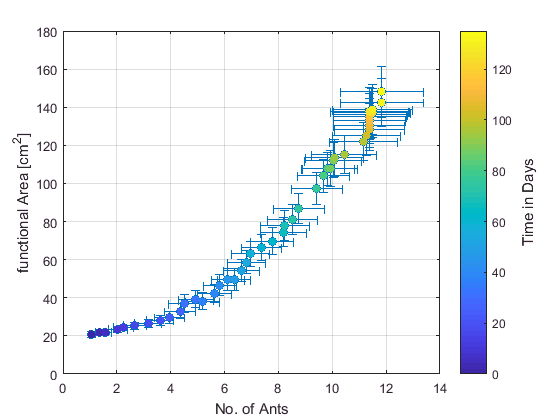

t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(1).Mean(t0:tend);
Aer = M(1).SEM(t0:tend);
N = M(13).Mean(t0:tend);
Ner = M(13).SEM(t0:tend);

figure
errorbar(N,A,Aer,Aer,Ner,Ner,'o')
hold on
scatter(N,A,[],t1,'filled')
xlabel('No. of Ants')
ylabel('functional Area [cm^2]')
grid on
c = colorbar;
c.Label.String = 'Time in Days'; c.Label.FontSize = 11;

%title('Mean fArea vs. Mean Population (error bars = SEM)- interpolated for missing values ')


## Linear fit from 5 workers

More5idx = find(N>=5);
N5 = N(More5idx);
A5 = A(More5idx);
t5 = t1(More5idx);
figure
scatter(N5,A5,[],t5)

lm = fitlm(N5,A5)

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________
    (Intercept)    -52.287      2.9077    -17.982    2.7343e-18
    x1              16.253     0.30443     53.387    7.4996e-33

Number of observations: 34, Error degrees of freedom: 32
Root Mean Squared Error: 3.77
R-squared: 0.989,  Adjusted R-Squared 0.989
F-statistic vs. constant model: 2.85e+03, p-value = 7.5e-33

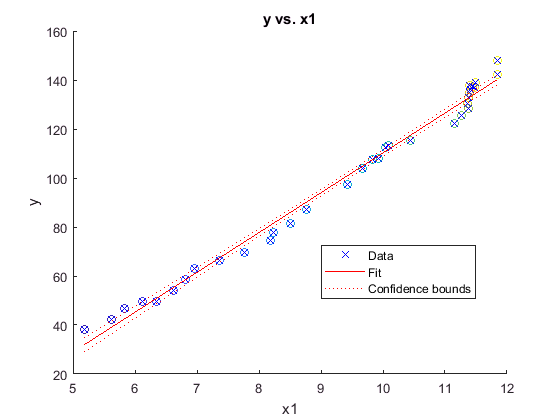

hold on
plot(lm)



sA5 = A5./N5;
MinimalSA = min(sA5)

MinimalSA = 7.3764

MaximalSA = max(sA5)

MaximalSA = 12.5104

MeanSA = mean(sA5)

MeanSA = 10.2909

SD_SA = std(sA5)

SD_SA = 1.5703

**Density model**

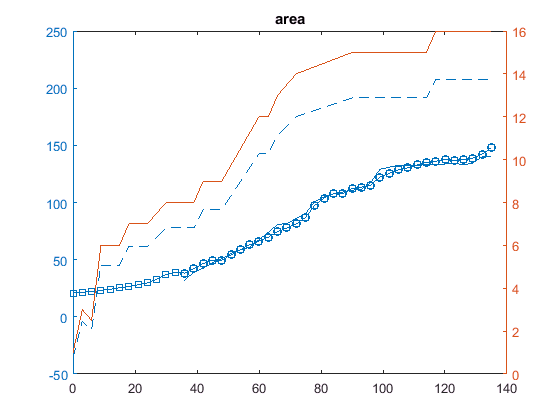

sA = A./N;
Apred = predict(lm,N);
A5pred = predict(lm,N5);
sA5pred = A5pred./N5;

figure;
yyaxis left
plot(t1,A,'-s',t5,A5,'-o',t5,A5pred,t1,Apred)
yyaxis right
plot(t1,N)
title('area')

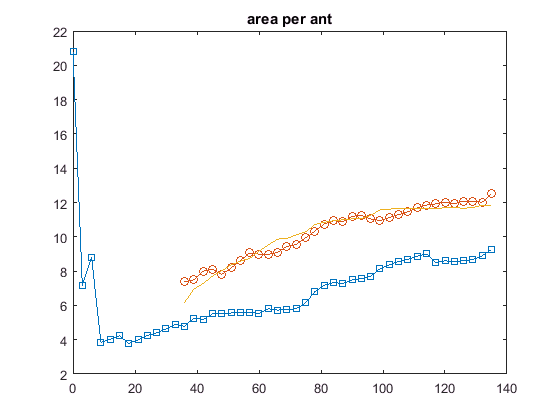


figure; plot(t1,sA,'-s',t5,sA5,'-o',t5,sA5pred)
title('area per ant')

## Plot 3 specific experiments (F3,F25,F29) pop vs. area plots

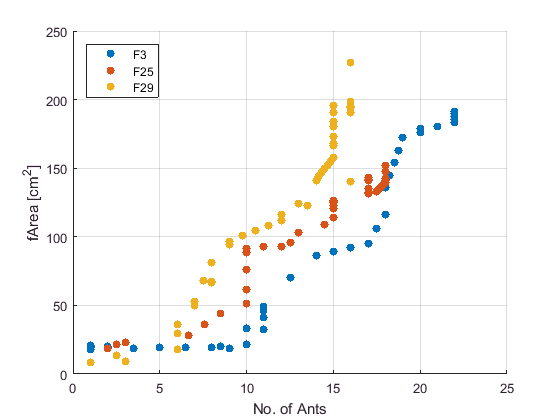

figure
for k=[3 25 29]
    hold on
    fA = S(k).B.fArea(t0:tend);
    N = S(k).B.SmoothPop(t0:tend);
    scatter(N,fA,'filled')
end
grid on
xlabel('No. of Ants')
ylabel('fArea [cm^2]')
legend({'F3','F25','F29'},'Location','northwest')

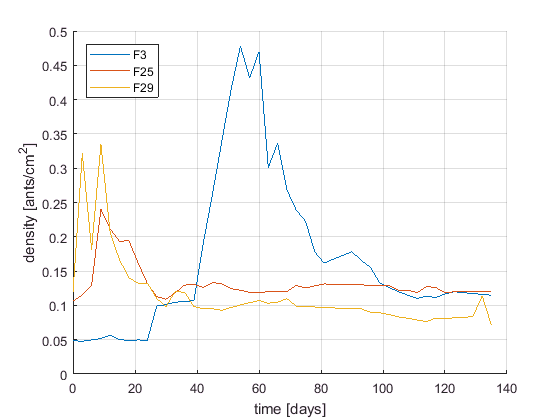


figure
for k=[3 25 29]
    hold on
    fA = S(k).B.fArea(t0:tend);
    N = S(k).B.SmoothPop(t0:tend);
    density = N./fA;
    plot(t1,density)
end
grid on
xlabel('time [days]')
ylabel('density [ants/cm^2]')
legend({'F3','F25','F29'},'Location','northwest')